# Loads 2 different networks.

### This example contains: 

- Load 2 Input files. 

- Load networks. 

- Disp elevations for the two networks. 

- Set new elevations. 

- Disp new elevations. 

- Disp computed values for the two networks.

- Plot networks. 

- Unload libraries.

### Clear - Start Toolkit 

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


### Load networks.

d1 = epanet('Net1.inp'); 

EPANET version {20200} loaded (EMT version {v2.2.003}).
Loading File "Net1.inp"...
Input File "Net1.inp" loaded sucessfuly.


d2 = epanet('Net2.inp');

EPANET version {20200} loaded (EMT version {v2.2.003}).
Loading File "Net2.inp"...
Input File "Net2.inp" loaded sucessfuly.


### Disp elevations for the two networks.

disp('Net1 - Elevations:')

Net1 - Elevations:


disp('------------------')

------------------


d1_Elevs = d1.getNodeElevations;
disp(d1_Elevs)

   710   710   700   695   700   695   690   700   710   800   850



disp('Net2 - Elevations:')

Net2 - Elevations:


disp('------------------')

------------------


d2_Elevs = d2.getNodeElevations;
disp(d2_Elevs)

  Columns 1 through 20

    50   100    60    60   100   125   160   110   180   130   185   210   210   200   190   150   180   100   150   170

  Columns 21 through 36

   150   200   230   190   230   130   110   110   130   190   110   180   190   110   110   235



### Set new elevations.

disp('Net1 - New Elevations:')

Net1 - New Elevations:


disp('------------------')

------------------


d1.setNodeElevations(d1_Elevs + 200);
disp(d1.getNodeElevations)

  Columns 1 through 10

         910         910         900         895         900         895         890         900         910        1000

  Column 11

        1050



disp('Net2 - New Elevations:')

Net2 - New Elevations:


disp('------------------')

------------------


d2.setNodeElevations(d2_Elevs + 200);
disp(d2.getNodeElevations)

  Columns 1 through 20

   250   300   260   260   300   325   360   310   380   330   385   410   410   400   390   350   380   300   350   370

  Columns 21 through 36

   350   400   430   390   430   330   310   310   330   390   310   380   390   310   310   435



### Disp computed values for the two networks.

disp('Net1 - Computed Time Series Values:')

Net1 - Computed Time Series Values:


disp('-----------------------------------')

-----------------------------------


disp(d1.getComputedTimeSeries)

              Time: [25×1 double]
          Pressure: [25×11 double]
            Demand: [25×11 double]
              Head: [25×11 double]
       NodeQuality: [25×11 double]
              Flow: [25×13 double]
          Velocity: [25×13 double]
          HeadLoss: [25×13 double]
            Status: [25×13 double]
           Setting: [25×13 double]
      ReactionRate: [25×13 double]
    FrictionFactor: [25×13 double]
       LinkQuality: [25×13 double]
         StatusStr: {25×13 cell}



disp('Net2 - Computed Time Series Values:')

Net2 - Computed Time Series Values:


disp('-----------------------------------')

-----------------------------------


disp(d2.getComputedTimeSeries)

              Time: [56×1 double]
          Pressure: [56×36 double]
            Demand: [56×36 double]
              Head: [56×36 double]
       NodeQuality: [56×36 double]
              Flow: [56×40 double]
          Velocity: [56×40 double]
          HeadLoss: [56×40 double]
            Status: [56×40 double]
           Setting: [56×40 double]
      ReactionRate: [56×40 double]
    FrictionFactor: [56×40 double]
       LinkQuality: [56×40 double]
         StatusStr: {56×40 cell}



### Plot networks.

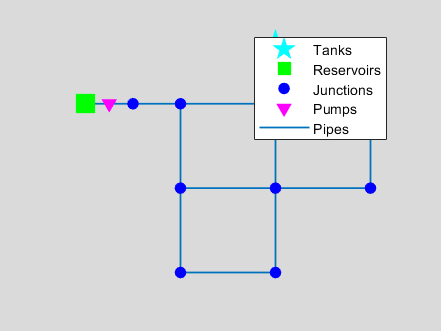

d1.plot;

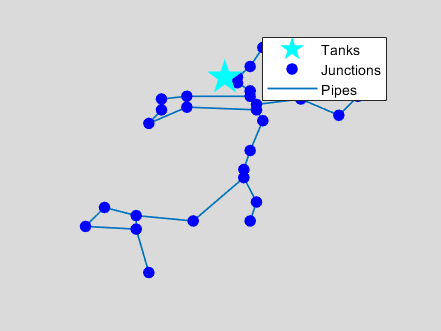

d2.plot;

### Unload libraries.

d1.unload;

EPANET Class is unloaded


d2.unload;

EPANET Class is unloaded
